# Ejercicio 3. Análisis de Componentes

### Procesado Óptico y Digital de Señales e Imágenes.  

#### Tarea propuesta: 

Obtención del componente principal en los datos formados por dos variables.

**a)** Se han tomado numerosas muestras de un proceso, y para cada muestra se ha medido el valor de dos variables. Los valores de las muestras para cada una de las variables están contenidos en var1.mat y var2.mat. Carga y representa los datos.

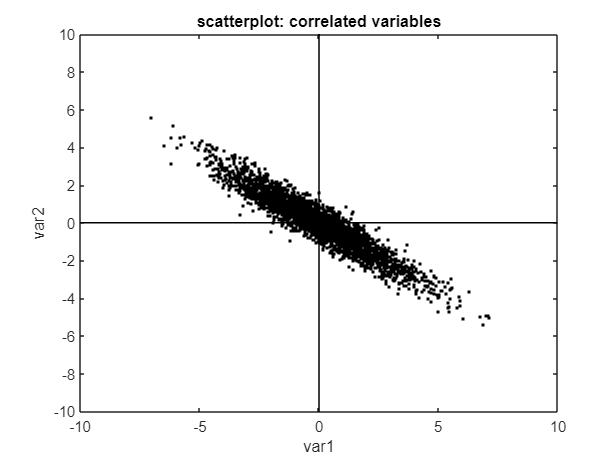

clear all
close all

load('var1.mat')
load('var2.mat')

var = [var1;var2];

me = mean(var,2);
var = var - me;

plot(var(1,:),var(2,:),'k.'); hold on
plot([-10,10],[0,0],'k')
plot([0,0],[-10,10],'k')
axis([-10 10 -10 10]);
title('scatterplot: correlated variables');
xlabel('var1'); ylabel('var2');

`Cargamos las variables var1 y var2 con el comando load() para generar un diagrama 2D con ellas.`

`Al representar una variable frente a otra se distingue una correlación muy fuerte entre ellas. Si las variables no estuvieran correlacionadas la dispersión sería similar en todo el plano. Aquí se observa una dispersión muy marcada en una dirección. Esta dirección define la combinación de las señales que contiene mayor información de todo el sistema.`

`Si solo nos quedamos con la dimensión en la que aparece la mayor dispersión la información perdida al reducir las dimensionnes se minimiza.`

X=[var1;var2];
Sx=cov(X');

**b)** Obtén los componentes principales por el procedimiento PCA y represéntalos sobre los datos anteriores. Representa el primer y segundo componente principal en rojo y verde respectivamente.

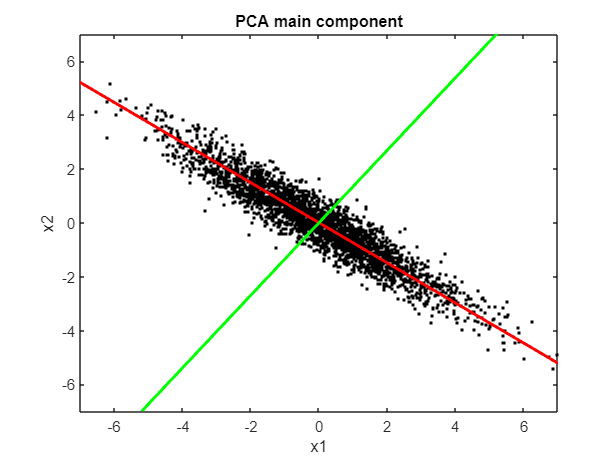

X = var - repmat(me,1,N);
A = X'/sqrt(N-1);
[U,S,V] = svd(A);
SD = diag(S);
vr = SD.*SD;
prd= V'*X; %data projection

figure()
plot(X(1,:),X(2,:),'k.');hold on;
plot([-10*V(1,1) 10*V(1,1)],[-10*V(2,1) 10*V(2,1)],'r','LineWidth',2);
plot([-10*V(1,2) 10*V(1,2)],[-10*V(2,2) 10*V(2,2)],'g','LineWidth',2);
axis([-7 7 -7 7]);
title('PCA main component'); xlabel('x1'); ylabel('x2');

`En rojo y verde se marcan las componentes principales. La variable prd contiene la información de los datos proyectados sobre sendas componentes. Si nos quedamos solo con la primera de sus columnas estaríamos reducciendo la dimensión del sistema perdiendo la mímina información posible (componente principal). Al contrario con la segunda columna, generada a partir de la componente con menor correlación. Esta componente contiene la menor información del sistema correlacionado.`

**c)** Realiza el cambio de coordenadas de los datos para representarlos según sus componentes principales.

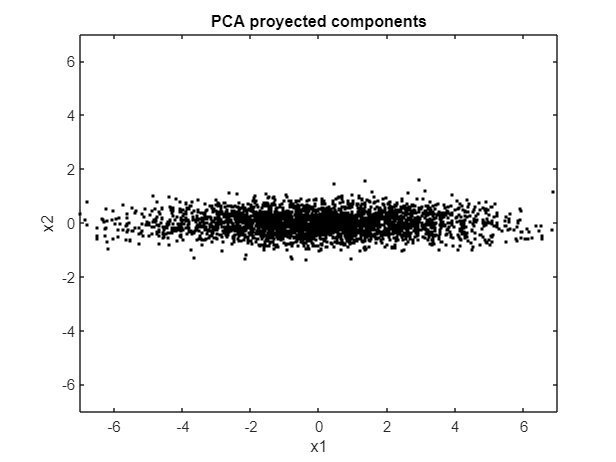

figure()
plot(prd(1,:),prd(2,:),'k.');hold on;
title('PCA proyected components'); xlabel('x1'); ylabel('x2');
axis([-7 7 -7 7]);

**d)** Reduce la dimensionalidad de los datos, usando un único componente principal

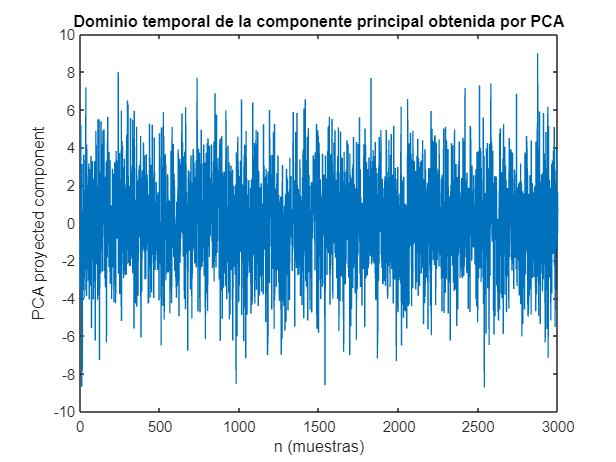

figure()
plot(prd(1,:))
title('Dominio temporal de la componente principal obtenida por PCA')
xlabel('n (muestras)')
ylabel('PCA proyected component')

**Al tener un número tan grande de muestras no se alcanza a distinguir nada. La conclusión importante a la que llegamos en este punto es que, gracias al procedimiento PCA, hemos sido capaces de reducir la dimensionalidad del sistema. Computacionalmente esto puede resultar muy favorable. Repercutiendo directamente sobre los tiempos de cálculo que requeriría un posible procesamiento posterior de la señal. Sobre todo si el número de muestras es tan elevado.**